# Creates scenarios based on node count of inp file EPANET.

### This example contains: 

- Load a network. 

- Create scenario parameters. 

- Create Multiple Scenarios. 

- Set quality type. 

- Run Scenarios. 

- Get computed quality time series. 

- Plot Quality VS Time. 

- Unload library.

#### For more check out the S-PLACE Toolkit (Sensor placement Toolkit):

[https://github.com/KIOS-Research/splace-toolkit](https://github.com/KIOS-Research/splace-toolkit)

### Clear - Start Toolkit 

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


## Load a network.

d = epanet('Net1.inp');

EPANET version {20200} loaded (EMT version {v2.2.003}).
Loading File "Net1.inp"...
Input File "Net1.inp" loaded sucessfuly.


### **Create scenario parameters.**

#### TIMES

PatternTimeStep=d.TimePatternStep;
SimulationTime=48; %e.g.48 in Hours

#### CONTAMINANT (A)

SourceInjectionRate=10; %mg/L (Concentration), instead of mg/minute
SourcesInjectionTimes=[5 20]; %from...to in hours

#### Uncertainty

qunc=0.05;

### **Create Multiple Scenarios.**

#### Set quality type.

d.setQualityType('chem','mg/L')

d.setTimeSimulationDuration(SimulationTime*3600);

### ** Run Scenarios.**

disp(['Number of Scenarios = NodeCount: ', num2str(d.getNodeCount)])

Number of Scenarios = NodeCount: 11



for n = 1:d.getNodeCount
    disp(['Scenario: ', num2str(n)])
    
    Diameters = add_unc(d.LinkDiameter, qunc);
    Lengths = add_unc(d.LinkLength, qunc);
    Roughness = add_unc(d.LinkRoughnessCoeff, qunc);
    Elevation = add_unc(d.NodeElevations, qunc);
    BaseDemand = add_unc(d.NodeBaseDemands{1}, qunc);
    tmpPat = d.Pattern;
    for i = 1:size(tmpPat, 1)
        Pattern = add_unc(tmpPat(i, :), qunc);
    end

    d.setLinkDiameter(Diameters)
    d.setLinkLength(Lengths)
    d.setLinkRoughnessCoeff(Roughness)
    d.setNodeElevations(Elevation)
    d.setNodeBaseDemands({BaseDemand})
    d.setPatternMatrix(Pattern)

    d.setTimeQualityStep(PatternTimeStep);
    zeroNodes=zeros(1,d.NodeCount);
    d.setNodeInitialQuality(zeroNodes);
    d.setLinkBulkReactionCoeff(zeros(1,d.LinkCount));
    d.setLinkWallReactionCoeff(zeros(1,d.LinkCount));

    patlen=(SimulationTime)*3600/PatternTimeStep;
    
    % Add pattern
    tmppat=zeros(1,patlen);
    tmpstartstep=SourcesInjectionTimes(1);
    tmpendstep=SourcesInjectionTimes(2);
    tmppat(tmpstartstep:tmpendstep)=1;
    tmp1=d.addPattern(['CONTAMINANT_', char(n)],tmppat);
    tmpinjloc=n; %index of node
    tmp2=zeroNodes;
    if tmpinjloc~=0
        tmp2(tmpinjloc)=tmp1;
        nd_index = find(tmp2, 1);
        d.setNodeSourceType(nd_index, 'SETPOINT');
        d.setNodeSourcePatternIndex(tmp2);
        tmp2 = zeroNodes;
        tmp2(tmpinjloc)=SourceInjectionRate;
        d.setNodeSourceQuality(tmp2)
    end
    
    % Get computed quality time series.
    res = d.getComputedQualityTimeSeries;
    CN{n}= res.NodeQuality;
    %CL{n}= res.Linkuality;
end

Scenario: 1
Scenario: 2
Scenario: 3
Scenario: 4
Scenario: 5
Scenario: 6
Scenario: 7
Scenario: 8
Scenario: 9
Scenario: 10
Scenario: 11


### Plot Quality VS Time.

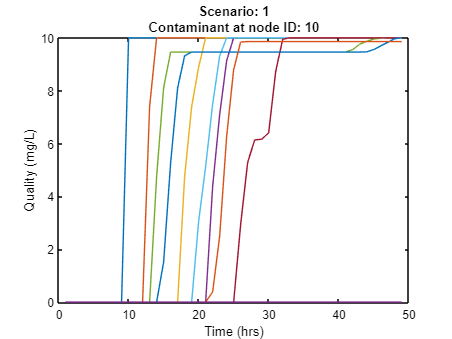

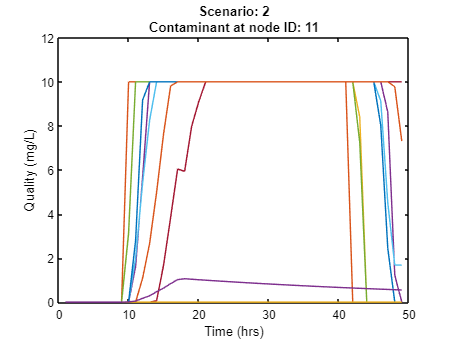

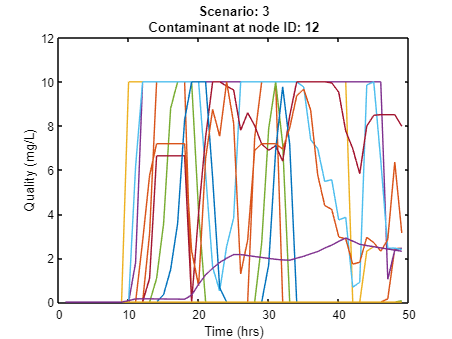

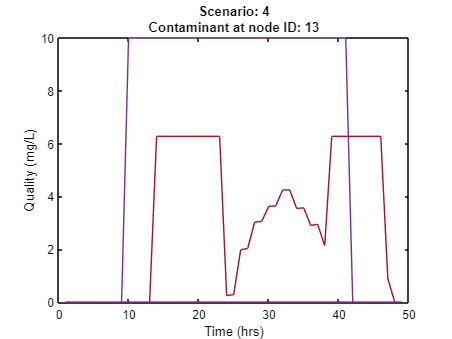

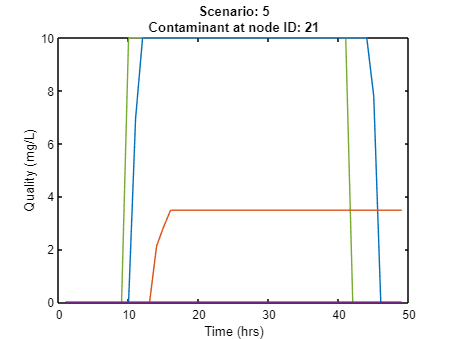

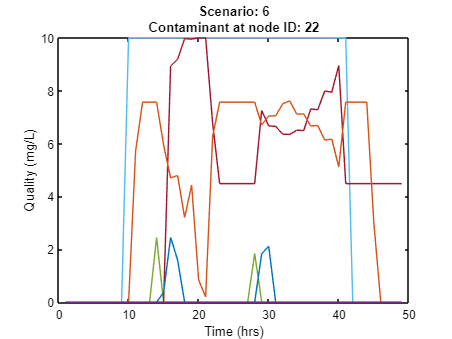

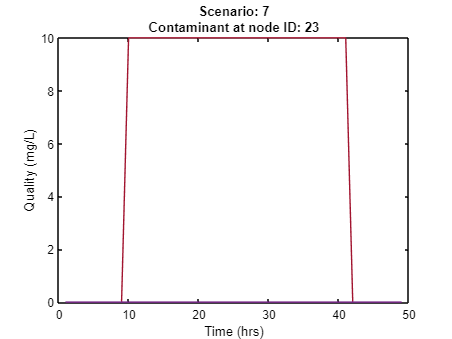

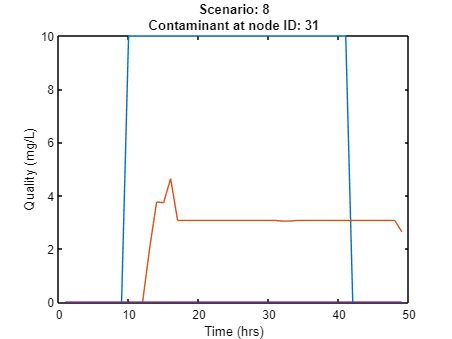

for i= 1:11
    figure;
    plot(CN{i})
    title({['Scenario: ', num2str(i)], ['Contaminant at node ID: ', d.getNodeNameID{i}]})
    xlabel('Time (hrs)')
    ylabel('Quality (mg/L)')
end

### Unload library.

d.unload;

EPANET Class is unloaded


function value_unc = add_unc(qext, qunc)
    ql=qext-qunc*qext;
    qu=qext+qunc*qext;
    value_unc=ql+rand(1,length(qext)).*(qu-ql);
end